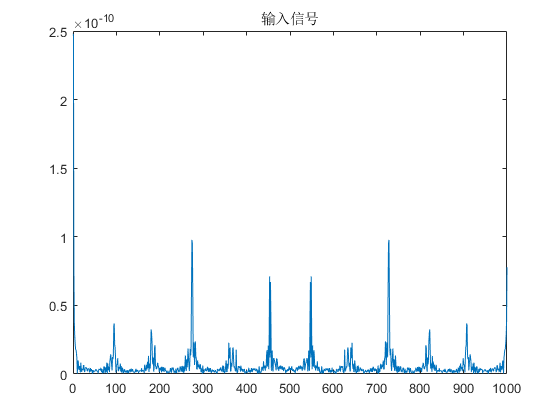

n=0:999;
x=sin(pi*n*4);
figure
plot(abs(fft(x)));title('输入信号');

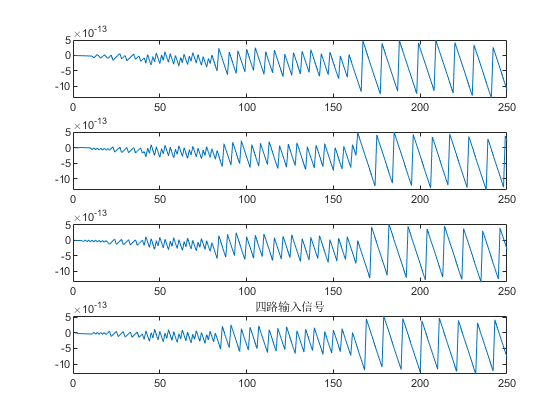

wn=0.5;N=1000;
xx=reshape(x,4,250);
x1=xx(1,:);
x2=xx(2,:);
x3=xx(3,:);
x4=xx(4,:); 
figure(2)
subplot 411;plot(x1);
subplot 412;plot(x2);
subplot 413;plot(x3);
subplot 414;plot(x4);
title('四路输入信号')

hn=fir1(N-1,wn);
h=hn(n+1);
hh=reshape(h,4,250);
h1=xx(1,:);
h2=xx(2,:);
h3=xx(3,:);
h4=xx(4,:);
H1=abs(fft(h1,250));
H2=abs(fft(h2,250));
H3=abs(fft(h3,250));
H4=abs(fft(h4,250));
H=filter(x,h);

错误使用 filter
输入参数的数目不足。

figure
plot(H);title('滤波器的频域波形');
figure(4)
subplot 411;plot(H1);
subplot 412;plot(H2);
subplot 413;plot(H3);
subplot 414;plot(H4);
title('子滤波器的频域波形');
y1=conv(x1,h1);
y2=conv(x2,h2);
y3=conv(x3,h3);
y4=conv(x4,h4);
y=y1+y2+y3+y4;
Y=abs(fft(y));
figure;
subplot 211; plot(y);
subplot 212; plot(Y);
title('输出信号的时域、频域波形图')